# Calibration ToF

## Import data

clc; clear; close all;

line = load("../trainingData/calib2_straight.mat");
GT_position = squeeze(line.out.GT_position.signals.values);
GT_rotation = squeeze(line.out.GT_rotation.signals.values);
GT_time = squeeze(line.out.GT_position.time);
ToF1_raw = squeeze(line.out.Sensor_ToF1.signals.values)';
ToF2_raw = squeeze(line.out.Sensor_ToF2.signals.values)';
ToF3_raw = squeeze(line.out.Sensor_ToF3.signals.values)';
ToF_time = squeeze(line.out.Sensor_ToF1.time)';

% Magnitometer Data
Mraw = squeeze(line.out.Sensor_MAG.signals.values)';
M_time = squeeze(line.out.Sensor_MAG.time)';
Mx   = Mraw(:,2);
My   = Mraw(:,3);
% Combine for 2D
XY_raw = [Mx, My];

## Magnitometer check

#### Apply

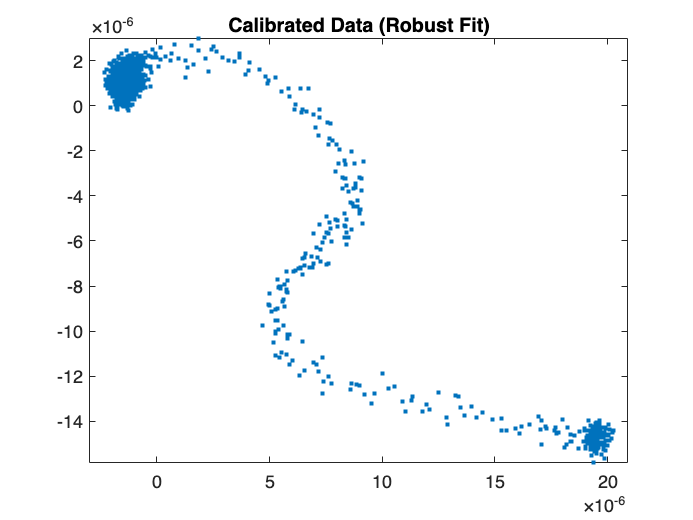

calParams = load("../MAG_calParams.mat");
[calMag, yaw_mag]= applyMagnetometerCalibration2D(XY_raw, calParams.calParams);

figure;
plot(calMag(:,1), calMag(:,2), '.');
title('Calibrated Data (Robust Fit)'); 
axis equal;

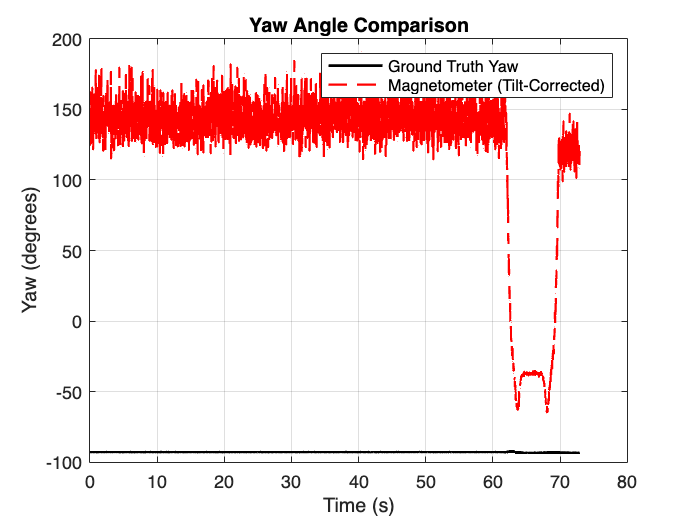


yaw_gt = quat2eul(GT_rotation, 'ZXY');  % [yaw, pitch, roll]
yaw_gt = yaw_gt(:,1);                   % Take yaw only (in radians)
yaw_gt = unwrap(yaw_gt);    % Unwrap to prevent jumps at ±π


figure;
plot(GT_time, rad2deg(yaw_gt), 'k', 'LineWidth', 1.5); hold on;
plot(M_time, rad2deg(yaw_mag), 'r--', 'LineWidth', 1.2);
xlabel('Time (s)'); ylabel('Yaw (degrees)');
legend('Ground Truth Yaw', 'Magnetometer (Tilt-Corrected)');
title('Yaw Angle Comparison');
grid on;

It seems like there are significant outliers after 60 Seconds, therefore, only 1st 60 seconds will be taken for calibration.

% Logical index for first 60 seconds
gt_mask = GT_time <= 60;
tof_mask = ToF_time <= 60;

% Apply the mask
GT_time = GT_time(gt_mask);
GT_position = GT_position(gt_mask, :);  % if GT_position is Nx2 or Nx3

ToF_time = ToF_time(tof_mask);
ToF1_raw = ToF1_raw(tof_mask);
ToF2_raw = ToF2_raw(tof_mask);
ToF3_raw = ToF3_raw(tof_mask);